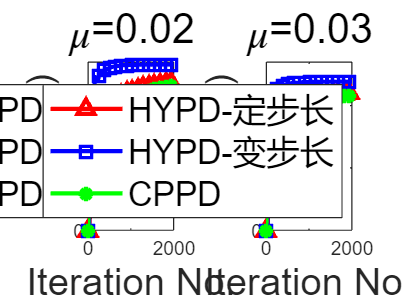

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = 1;

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 2000;
opts1.snr = 50;
[reimed1_1,outs1_1] = cp_tv_me(fn1,W,beita,rows,cols,im,opts1);
[reimed1_2,outs1_2] = hypd_tv_me2(fn1,W,beita,rows,cols,im,opts1);
[reimed1_3,outs1_3] = hypd_tv_me2_adaptive(fn1,W,beita,rows,cols,im,opts1);
[reimed2_1,outs2_1] = cp_tv_me(fn2,W,beita,rows,cols,im,opts1);
[reimed2_2,outs2_2] = hypd_tv_me2(fn2,W,beita,rows,cols,im,opts1);
[reimed2_3,outs2_3] = hypd_tv_me2_adaptive(fn2,W,beita,rows,cols,im,opts1);



%% 绘图
Xaxis = (0:10:2000);dx=floor(length(Xaxis)/15);
subplot(121);
plot(Xaxis,outs1_2.snr(Xaxis+1),'r-','LineWidth',1.8,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1_3.snr(Xaxis+1),'b-','LineWidth',1.8,'Marker','s','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs1_1.snr(Xaxis+1),'g-','LineWidth',1.8,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold off;
axis([Xaxis(1),Xaxis(end),0,27]);
legend('HYPD-定步长','HYPD-变步长','CPPD','FontSize',14,'Location','SouthEast');
xlabel('Iteration No.','FontSize',16);ylabel('SNR(dB)','FontSize',15);title('\mu=0.02','FontSize',17);

subplot(122);
plot(Xaxis,outs2_2.snr(Xaxis+1),'r-','LineWidth',1.8,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2_3.snr(Xaxis+1),'b-','LineWidth',1.8,'Marker','s','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(Xaxis,outs2_1.snr(Xaxis+1),'g-','LineWidth',1.8,'Marker','*','MarkerIndices',1:dx:length(Xaxis));hold off;
axis([Xaxis(1),Xaxis(end),0,27]);
legend('HYPD-定步长','HYPD-变步长','CPPD','FontSize',14,'Location','SouthEast');
xlabel('Iteration No.','FontSize',16);ylabel('SNR(dB)','FontSize',15);title('\mu=0.03','FontSize',17);

% set(gcf,'unit','centimeters','position',[1,2,30,10])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg3.CPPDcompare.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg3.CPPDcompare.fig')

clear;clf;
%% 设置一个图像重建问题
n = 128; % n*n个像素
im = phantom(n);  % 测试图像：头骨图
alpha = [0.02,0.03];
noisy1 = im + alpha(1)*randn(size(im)); %添加高斯噪声
noisy2 = im + alpha(2)*randn(size(im)); %添加高斯噪声
snr0_1 = 20*log10(norm(im,'fro')/norm(noisy1-im,'fro'));
snr0_2 = 20*log10(norm(im,'fro')/norm(noisy2-im,'fro'));
beita = 1;

[rows,cols] = size(im);
%% 构造radon变换矩阵W
dtheta = 2; % radon变换扫描的角度间隔，如theta=1时，角度为0:1:179
W = CWM(1,dtheta,rows,cols);
fn1 = W*noisy1(:);fn2 = W*noisy2(:);

%% 重建
opts1 = [];
opts1.maxIters = 200000;
opts1.T = 20;
opts1.snr = 50;

%% SART算法
it_sart = 5e3;
Tsart = tic;
lambda_sart = 1.9;
[y_sart1,outs3_11] = sart_stop(fn1,W,lambda_sart,it_sart,im);
toc(Tsart)

历时 10.310310 秒。


u_sart1 = reshape(y_sart1,rows,cols);
beita2 = 25;opts2_2=[];opts2_2.gamma=1.9;opts2_2.maxIters=1e5;opts2_2.T=15;
[u_sart_denoisy1,outs3_21] = hypd2_tv_rof(u_sart1,beita2,im,opts2_2);
snr_sart1 = 20*log10(norm(im,'fro')/norm(u_sart1-im,'fro'));
snr_sart_denoisyed1 = 20*log10(norm(im,'fro')/norm(u_sart_denoisy1-im,'fro'));
%% SART算法，按迭代次数停止
it_sart = 6e3;
lambda_sart = 1.9;
[~,outs_sart1] = sart(fn1,W,lambda_sart,it_sart,im,rows,cols);


[reimed1_2,outs1_2] = hypd_tv_me2(fn1,W,beita,rows,cols,im,opts1);
[reimed1_3,outs1_3] = hypd_tv_me2_adaptive(fn1,W,beita,rows,cols,im,opts1);


%% SART算法
it_sart = 5e3;
Tsart = tic;
lambda_sart = 1.9;
[y_sart2,outs3_12] = sart_stop(fn2,W,lambda_sart,it_sart,im);
toc(Tsart)

历时 5.986532 秒。


u_sart2 = reshape(y_sart2,rows,cols);
beita2 = 25;
[u_sart_denoisy2,outs3_22] = hypd2_tv_rof(u_sart2,beita2,im,opts2_2);
snr_sart2 = 20*log10(norm(im,'fro')/norm(u_sart2-im,'fro'));
snr_sart_denoisyed2 = 20*log10(norm(im,'fro')/norm(u_sart_denoisy2-im,'fro'));
%% SART算法，按迭代次数停止
it_sart = 6e3;
lambda_sart = 1.9;
[~,outs_sart2] = sart(fn2,W,lambda_sart,it_sart,im,rows,cols);

[reimed2_2,outs2_2] = hypd_tv_me2(fn2,W,beita,rows,cols,im,opts1);
[reimed2_3,outs2_3] = hypd_tv_me2_adaptive(fn2,W,beita,rows,cols,im,opts1);




## 绘图

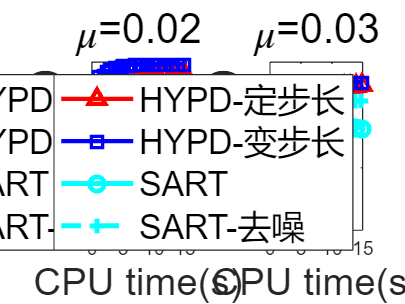

Xaxis = (1:1:151);dx=floor(length(Xaxis)/15);
subplot(121);

plot(outs1_2.snrT(Xaxis,1),outs1_2.snrT(Xaxis,2),'r-','LineWidth',1.8,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(outs1_3.snrT(Xaxis,1),outs1_3.snrT(Xaxis,2),'b-','LineWidth',1.8,'Marker','s','MarkerIndices',1:dx:length(Xaxis));hold on;

t2 = outs3_11.snrT(end,1);X2 = 1:Xaxis(end)-t2*10;
plot(outs_sart1.snrT(Xaxis,1),outs_sart1.snrT(Xaxis,2),'c-','LineWidth',2,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(t2+outs3_21.snrT(X2,1),outs3_21.snrT(X2,2),'c--','LineWidth',2,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;
axis([outs1_2.snrT(Xaxis(1),1),outs1_2.snrT(Xaxis(end),1),0,27]);

legend('HYPD-定步长','HYPD-变步长','SART','SART-去噪','FontSize',14,'Location','SouthEast');
xlabel('CPU time(s)','FontSize',16);ylabel('SNR(dB)','FontSize',16);title('\mu=0.02','FontSize',17);

subplot(122);

plot(outs2_2.snrT(Xaxis,1),outs2_2.snrT(Xaxis,2),'r-','LineWidth',1.8,'Marker','^','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(outs2_3.snrT(Xaxis,1),outs2_3.snrT(Xaxis,2),'b-','LineWidth',1.8,'Marker','s','MarkerIndices',1:dx:length(Xaxis));hold on;

t22 = outs3_12.snrT(end,1);X22 = 1:Xaxis(end)-t22*10;
plot(outs_sart2.snrT(Xaxis,1),outs_sart2.snrT(Xaxis,2),'c-','LineWidth',2,'Marker','o','MarkerIndices',1:dx:length(Xaxis));hold on;
plot(t2+outs3_22.snrT(X2,1),outs3_22.snrT(X2,2),'c--','LineWidth',2,'Marker','+','MarkerIndices',1:dx:length(Xaxis));hold off;
axis([outs1_2.snrT(Xaxis(1),1),outs1_2.snrT(Xaxis(end),1),0,27]);


legend('HYPD-定步长','HYPD-变步长','SART','SART-去噪','FontSize',14,'Location','SouthEast');
xlabel('CPU time(s)','FontSize',16);ylabel('SNR(dB)','FontSize',16);title('\mu=0.03','FontSize',17);

% set(gcf,'unit','centimeters','position',[1,2,30,10])
% exportgraphics(gcf,'E:\毕设\论文\投稿\test\images\tg4.SARTcompare.eps');
% savefig(gcf,'E:\毕设\源码\test\PD\源图\tg4.SARTcompare.fig')